To ensure that directory is in the correct location

clear
dir

.                         Data                      Regression.mlx            
..                        ElectionOptimization.mlx  



Importing data

DemocratDisbursement = readmatrix('Data/FinalHouseData/DemocratDisbursement.csv');
RepublicanDisbursement = readmatrix('Data/FinalHouseData/RepublicanDisbursement.csv');
HouseDistrictdata = readtable('Data/CongressionalDistricts.csv','ReadVariableNames',0);

Check data bounds

DataSize = size(DemocratDisbursement);
DisbursementSize = DataSize(1);

Problem 1: Campaign spending has increased from year to year, making the prediction of spending dependent upon the selected year.

Solution: Represent disbursements as percentages of that year's grand total. Allowing for the formulation of equations that fit no matter the predicted grand total.

DProportionalMatrix = zeros(40,DataSize(2)-1);
RProportionalMatrix = zeros(40,DataSize(2)-1);
for i = 1:40
    for j = 1:DataSize(2)-1
        DProportionalMatrix(i,j) = DemocratDisbursement(i,j)/DemocratDisbursement(ceil(i/4),436);
        RProportionalMatrix(i,j) = RepublicanDisbursement(i,j)/RepublicanDisbursement(ceil(i/4),436);
    end
end

Create linear regression formulas for each time step. (x0,x1) -> 1:2  (x2,x3,x4) -> 2:3 (x5,x6,x7,x8) -> 3:4

There will be one formula per seat.

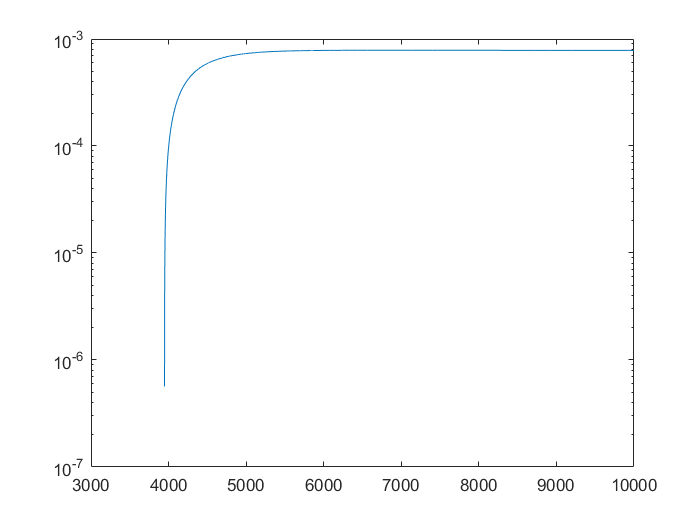

DLinearMatrix = zeros(6,DataSize(2)-1);
RLinearMatrix = zeros(6,DataSize(2)-1);
CostHistory = zeros(3,2);
CostGraphOne = zeros(10000,1);
CostGraphTwo = zeros(10000,1);
CostGraphThree = zeros(10000,1);
for j = 1:435
    CostHistoryT = zeros(3,2);
    DOneTwoMatrix = zeros(10,1);
    DAnswerOneTwoMatrix = zeros(10,1);
    DOneThreeMatrix = zeros(10,1);
    DAnswerOneThreeMatrix = zeros(10,1);
    DOneFourMatrix = zeros(10,1);
    DAnswerOneFourMatrix = zeros(10,1);
    ROneTwoMatrix = zeros(10,1);
    RAnswerOneTwoMatrix = zeros(10,1);
    ROneThreeMatrix = zeros(10,1);
    RAnswerOneThreeMatrix = zeros(10,1);
    ROneFourMatrix = zeros(10,1);
    RAnswerOneFourMatrix = zeros(10,1);
    for i = 1:10
        if(DProportionalMatrix(4+((i-1)*4),j) == 0)
            DOneTwoMatrix(i,1) = -1;
            DAnswerOneTwoMatrix(i,1) = -1;
            DOneThreeMatrix(i,1) = -1;
            DAnswerOneThreeMatrix(i,1) = -1;
            DOneFourMatrix(i,1) = -1;
            DAnswerOneFourMatrix(i,1) = -1;
        else
            DOneTwoMatrix(i,1) = DProportionalMatrix(1+((i-1)*4),j);
            DAnswerOneTwoMatrix(i,1) = DProportionalMatrix(2+((i-1)*4),j);
            DOneThreeMatrix(i,1) = DProportionalMatrix(2+((i-1)*4),j);
            DAnswerOneThreeMatrix(i,1) = DProportionalMatrix(3+((i-1)*4),j);
            DOneFourMatrix(i,1) = DProportionalMatrix(3+((i-1)*4),j);
            DAnswerOneFourMatrix(i,1) = DProportionalMatrix(4+((i-1)*4),j);
        end
        if(RProportionalMatrix(4+((i-1)*4),j) == 0)
            ROneTwoMatrix(i,1) = -1;
            RAnswerOneTwoMatrix(i,1) = -1;
            ROneThreeMatrix(i,1) = -1;
            RAnswerOneThreeMatrix(i,1) = -1;
            ROneFourMatrix(i,1) = -1;
            RAnswerOneFourMatrix(i,1) = -1;
        else
            ROneTwoMatrix(i,1) = RProportionalMatrix(1+((i-1)*4),j);
            RAnswerOneTwoMatrix(i,1) = RProportionalMatrix(2+((i-1)*4),j);
            ROneThreeMatrix(i,1) = RProportionalMatrix(2+((i-1)*4),j);
            RAnswerOneThreeMatrix(i,1) = RProportionalMatrix(3+((i-1)*4),j);
            ROneFourMatrix(i,1) = RProportionalMatrix(3+((i-1)*4),j);
            RAnswerOneFourMatrix(i,1) = RProportionalMatrix(4+((i-1)*4),j);
        end
    end
    DOneTwoMatrix(DOneTwoMatrix(:, 1)== -1, :)= [];
    DOneThreeMatrix(DOneThreeMatrix(:, 1)== -1, :)= [];
    DOneFourMatrix(DOneFourMatrix(:, 1)== -1, :)= [];
    DAnswerOneTwoMatrix(DAnswerOneTwoMatrix(:, 1)== -1, :)= [];
    DAnswerOneThreeMatrix(DAnswerOneThreeMatrix(:, 1)== -1, :)= [];
    DAnswerOneFourMatrix(DAnswerOneFourMatrix(:, 1)== -1, :)= [];
    ROneTwoMatrix(ROneTwoMatrix(:, 1)== -1, :)= [];
    ROneThreeMatrix(ROneThreeMatrix(:, 1)== -1, :)= [];
    ROneFourMatrix(ROneFourMatrix(:, 1)== -1, :)= [];
    RAnswerOneTwoMatrix(RAnswerOneTwoMatrix(:, 1)== -1, :)= [];
    RAnswerOneThreeMatrix(RAnswerOneThreeMatrix(:, 1)== -1, :)= [];
    RAnswerOneFourMatrix(RAnswerOneFourMatrix(:, 1)== -1, :)= [];
    [DLinearMatrix(1:2,j),CostHistoryT(1,1),CDO] = Regression(DLinearMatrix(1:2,j),DOneTwoMatrix,DAnswerOneTwoMatrix,10000,.005);
    [DLinearMatrix(3:4,j),CostHistoryT(2,1),CDT] = Regression(DLinearMatrix(3:4,j),DOneThreeMatrix,DAnswerOneThreeMatrix,10000,.005);
    [DLinearMatrix(5:6,j),CostHistoryT(3,1),CDTH] = Regression(DLinearMatrix(5:6,j),DOneFourMatrix,DAnswerOneFourMatrix,10000,.005);
    [RLinearMatrix(1:2,j),CostHistoryT(1,2)] = Regression(RLinearMatrix(1:2,j),ROneTwoMatrix,RAnswerOneTwoMatrix,10000,.005);
    [RLinearMatrix(3:4,j),CostHistoryT(2,2)] = Regression(RLinearMatrix(3:4,j),ROneThreeMatrix,RAnswerOneThreeMatrix,10000,.005);
    [RLinearMatrix(5:6,j),CostHistoryT(3,2)] = Regression(RLinearMatrix(5:6,j),ROneFourMatrix,RAnswerOneFourMatrix,10000,.005);
    CostHistory = CostHistory + CostHistoryT;
    CostGraphOne(:,1) = CostGraphOne(:,1) + abs(CDO);
    CostGraphTwo(:,1) = CostGraphTwo(:,1) + abs(CDT);
    CostGraphThree(:,1) = CostGraphThree(:,1) + abs(CDTH);
end
figure
XCO = zeros(10000,1);
XCT = zeros(10000,1);
XCTH = zeros(10000,1);
for i = 1:10000
    XCO(i,1) =i;
    XCT(i,1) =i;
    XCTH(i,1) =i;
end
semilogy(XCO,CostGraphOne)

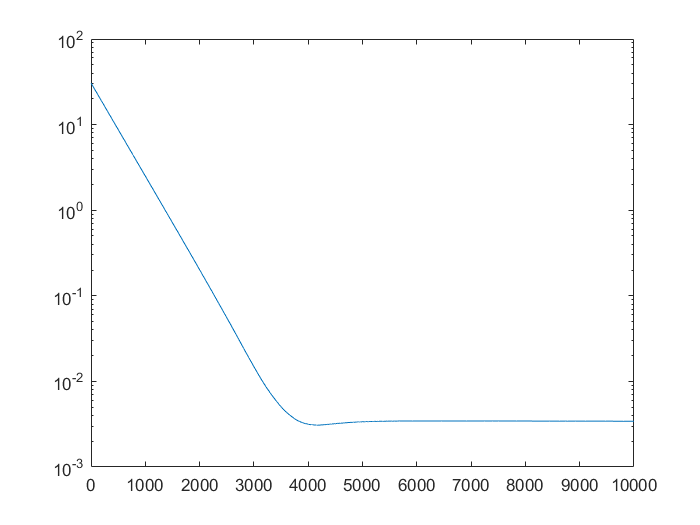

semilogy(XCT,CostGraphTwo)

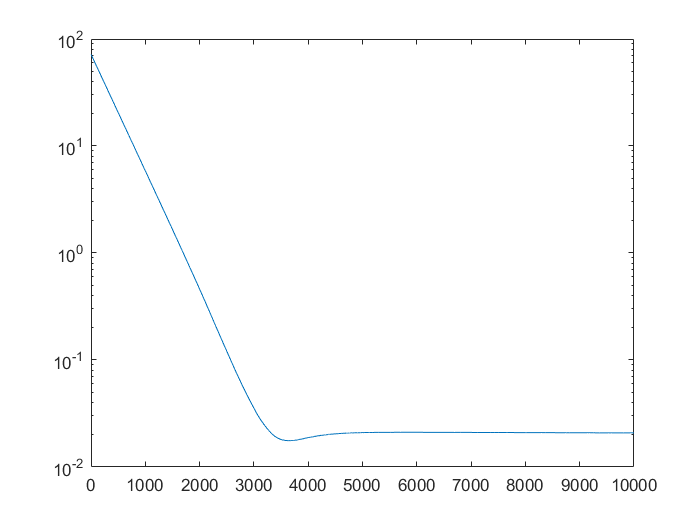

semilogy(XCTH,CostGraphThree)

T = array2table(CostHistory,'VariableNames',{'Democrat Cost','Republican Cost'})

T = 3×2 table
    Democrat Cost    Republican Cost
    _____________    _______________

     0.00078183         0.0017972   
       0.003412          0.008855   
       0.020814          0.044462   


MultiStage Stochastic Optimization requires T>2 Time steps as well as decision steps in between. Each time step will use the formula matrix to approximate the next series of disbursements. The approximations will be subject to a probability distribution that may increase or decrease additional disbursement by normal distribution with a mean of 1 and a standard deviation of .05. The objective function will be an election cycle 4th quarter's disbursement. Although many scenarios will be generated, complexity will be kept within  a certain bound by use of SAA to collapse the distributions.

%Select ProportionalMatrix and Linear Matrix of either party
ProportionalMatrix = DProportionalMatrix;
LinearMatrix = DLinearMatrix;
%Get Proportional Averages for 4th quarter
AverageProportion = zeros(1,435);
for i = 1:435
    Sum = 0;
    NotZero = 0;
    for j = 1:10
        if(ProportionalMatrix(4+((j-1)*4),i) ~= 0)
            NotZero = NotZero + 1;
            Sum = Sum + ProportionalMatrix(4+((j-1)*4),i);
        end
    end
    if(NotZero>0)
        AverageProportion(1,i) = Sum/NotZero; 
    end
end
%Preload with historical data for quarter 1
History = zeros(4,435);
History(1,:) = ProportionalMatrix(37,:);

format long;
iter = 100;
LossHistory = zeros(iter,1);
ProportionDonationHistory = zeros(iter,1);
ProportionDonationPrev = 1;
ProportionDonation = 1;
LearningRate = 5;
Direction = 1;
Loss = 0;
LossPrev =inf;
PredictedDisbursements = 500000000;
StartFunds = 12500000;
Scenarios = 100;
for h = 1:iter
CostTotal = 0;
for k = 1:10
Cost = 0;
Funds = StartFunds;
TotalFundsProportion = Funds/PredictedDisbursements;
ObjectiveFunction = zeros(1,435);
%Use linear matrix formulas with a normal probability distribution to
%determine 4th quarter disbursements proportions
for phase = 1:3
    if phase <2
        %One to Two
        for i = 1:435
            Temp=1*LinearMatrix(1,i) + History(1,i)*LinearMatrix(2,i);
            Sum = 0;
            for j = 1:Scenarios
                Sum =Sum + (Temp - History(1,i))*normrnd(1,0.00);
            end
            History(2,i)= History(1,i) + Sum/Scenarios;
        end
    end
    if phase<3
        %Two to Three
        for i = 1:435
            Sum = 0;
            Temp=1*LinearMatrix(3,i) + History(2,i)*LinearMatrix(4,i);
            for j = 1:Scenarios
                Sum =Sum + (Temp - History(2,i))*normrnd(1,0.00);
            end
            History(3,i)= History(2,i) + Sum/Scenarios;
        end
    end
    %Three to Four
    for i = 1:435
        Sum = 0;
        Temp=1*LinearMatrix(5,i) + History(3,i)*LinearMatrix(6,i);
        for j = 1:Scenarios
            Sum =Sum + (Temp - History(3,i))*normrnd(1,0.00);
        end
        History(4,i)= History(3,i) + Sum/Scenarios;
    end
    %Calculate Objective function
    % (Minimize AverageProportion(i) - History(i)(4)) where the difference > 0)
    for i = 1:435
        if(AverageProportion(1,i) > History(4,i))
            ObjectiveFunction(1,i) = AverageProportion(1,i) - History(4,i);
        end
    end
    %Decision on how much to donate to each seat dependent on keeping the
    %predicted value above the average
    for i = 1:435
        if(ObjectiveFunction(1,i)>0)
            if (ObjectiveFunction(1,i)*ProportionDonation < TotalFundsProportion)
                History(phase+1,i) = History(phase+1,i) + ObjectiveFunction(1,i)*ProportionDonation;
                TotalFundsProportion = TotalFundsProportion - ObjectiveFunction(1,i)*ProportionDonation;
            end
        end
    end
end

for i = 1:435
    if(AverageProportion(1,i) - History(4,i)>0)
        Cost = Cost + (AverageProportion(1,i) - History(4,i))^2;
    end
end

Cost = Cost;
CostTotal = CostTotal + Cost;
end 
Loss = CostTotal / 10;
if(Loss > LossPrev)
    Direction =Direction * -1;
    LearningRate = LearningRate/2
end

ProportionDonationHistory(h,1) = ProportionDonation;
LossHistory(h,1) = Loss;
%ProportionDonation = ProportionDonationPrev - Direction*LearningRate*Loss
ProportionDonation = ProportionDonationPrev - .01;
ProportionDonationPrev = ProportionDonation;
LossPrev = Loss;
h
end

h =      1


LearningRate =    2.500000000000000


h =      2


LearningRate =    1.250000000000000


h =      3


LearningRate =    0.625000000000000


h =      4


LearningRate =    0.312500000000000


h =      5


LearningRate =    0.156250000000000


h =      6


LearningRate =    0.078125000000000


h =      7


LearningRate =    0.039062500000000


h =      8


LearningRate =    0.019531250000000


h =      9


LearningRate =    0.009765625000000


h =     10


LearningRate =    0.004882812500000


h =     11


LearningRate =    0.002441406250000


h =     12


LearningRate =    0.001220703125000


h =     13


LearningRate =      6.103515625000000e-04


h =     14


LearningRate =      3.051757812500000e-04


h =     15


LearningRate =      1.525878906250000e-04


h =     16


LearningRate =      7.629394531250000e-05


h =     17


LearningRate =      3.814697265625000e-05


h =     18


LearningRate =      1.907348632812500e-05


h =     19


LearningRate =      9.536743164062500e-06


h =     20


LearningRate =      4.768371582031250e-06


h =     21


LearningRate =      2.384185791015625e-06


h =     22


LearningRate =      1.192092895507812e-06


h =     23


LearningRate =      5.960464477539062e-07


h =     24


LearningRate =      2.980232238769531e-07


h =     25


LearningRate =      1.490116119384766e-07


h =     26


LearningRate =      7.450580596923828e-08


h =     27


LearningRate =      3.725290298461914e-08


h =     28


LearningRate =      1.862645149230957e-08


h =     29


LearningRate =      9.313225746154785e-09


h =     30


LearningRate =      4.656612873077393e-09


h =     31


LearningRate =      2.328306436538696e-09


h =     32


LearningRate =      1.164153218269348e-09


h =     33


LearningRate =      5.820766091346741e-10


h =     34


LearningRate =      2.910383045673370e-10


h =     35


LearningRate =      1.455191522836685e-10


h =     36


LearningRate =      7.275957614183426e-11


h =     37


LearningRate =      3.637978807091713e-11


h =     38


LearningRate =      1.818989403545856e-11


h =     39


LearningRate =      9.094947017729282e-12


h =     40


LearningRate =      4.547473508864641e-12


h =     41


LearningRate =      2.273736754432321e-12


h =     42


LearningRate =      1.136868377216160e-12


h =     43


LearningRate =      5.684341886080801e-13


h =     44


LearningRate =      2.842170943040401e-13


h =     45


LearningRate =      1.421085471520200e-13


h =     46


LearningRate =      7.105427357601002e-14


h =     47


LearningRate =      3.552713678800501e-14


h =     48


LearningRate =      1.776356839400250e-14


h =     49


LearningRate =      8.881784197001252e-15


h =     50


LearningRate =      4.440892098500626e-15


h =     51


LearningRate =      2.220446049250313e-15


h =     52


LearningRate =      1.110223024625157e-15


h =     53


LearningRate =      5.551115123125783e-16


h =     54


LearningRate =      2.775557561562891e-16


h =     55


LearningRate =      1.387778780781446e-16


h =     56


LearningRate =      6.938893903907228e-17


h =     57


LearningRate =      3.469446951953614e-17


h =     58


LearningRate =      1.734723475976807e-17


h =     59


LearningRate =      8.673617379884035e-18


h =     60


LearningRate =      4.336808689942018e-18


h =     61


LearningRate =      2.168404344971009e-18


h =     62


LearningRate =      1.084202172485504e-18


h =     63


LearningRate =      5.421010862427522e-19


h =     64


LearningRate =      2.710505431213761e-19


h =     65


LearningRate =      1.355252715606881e-19


h =     66


LearningRate =      6.776263578034403e-20


h =     67


LearningRate =      3.388131789017201e-20


h =     68


LearningRate =      1.694065894508601e-20


h =     69


LearningRate =      8.470329472543003e-21


h =     70


LearningRate =      4.235164736271502e-21


h =     71


LearningRate =      2.117582368135751e-21


h =     72


LearningRate =      1.058791184067875e-21


h =     73


LearningRate =      5.293955920339377e-22


h =     74


LearningRate =      2.646977960169689e-22


h =     75


LearningRate =      1.323488980084844e-22


h =     76


LearningRate =      6.617444900424221e-23


h =     77


LearningRate =      3.308722450212111e-23


h =     78


LearningRate =      1.654361225106055e-23


h =     79


LearningRate =      8.271806125530277e-24


h =     80


LearningRate =      4.135903062765138e-24


h =     81


LearningRate =      2.067951531382569e-24


h =     82


LearningRate =      1.033975765691285e-24


h =     83


LearningRate =      5.169878828456423e-25


h =     84


LearningRate =      2.584939414228211e-25


h =     85


LearningRate =      1.292469707114106e-25


h =     86


LearningRate =      6.462348535570529e-26


h =     87


LearningRate =      3.231174267785264e-26


h =     88


LearningRate =      1.615587133892632e-26


h =     89


LearningRate =      8.077935669463161e-27


h =     90


LearningRate =      4.038967834731580e-27


h =     91


LearningRate =      2.019483917365790e-27


h =     92


LearningRate =      1.009741958682895e-27


h =     93


LearningRate =      5.048709793414476e-28


h =     94


LearningRate =      2.524354896707238e-28


h =     95


LearningRate =      1.262177448353619e-28


h =     96


LearningRate =      6.310887241768094e-29


h =     97


LearningRate =      3.155443620884047e-29


h =     98


LearningRate =      1.577721810442024e-29


h =     99


LearningRate =      7.888609052210118e-30


h =    100



ans = 0.0045;ans = 0.0050;
ans = 0.0043;ans = 0.0040;
ans = 0.0037;ans = 0.0035;
ans = 0.0031;ans = 0.0033;
ans = 0.0027;ans = 0.0033;
ans = 0.0021;ans = 0.0041;
ans = 0.0016;ans = 0.0048;
ans = 0.0012;ans = 0.0051;
ans = 0.0012;ans = 0.0049;
ans = 0.0015;ans = 0.0054;
ans = 0.0027;
ans = 0.0027;
ans = 0.0039;

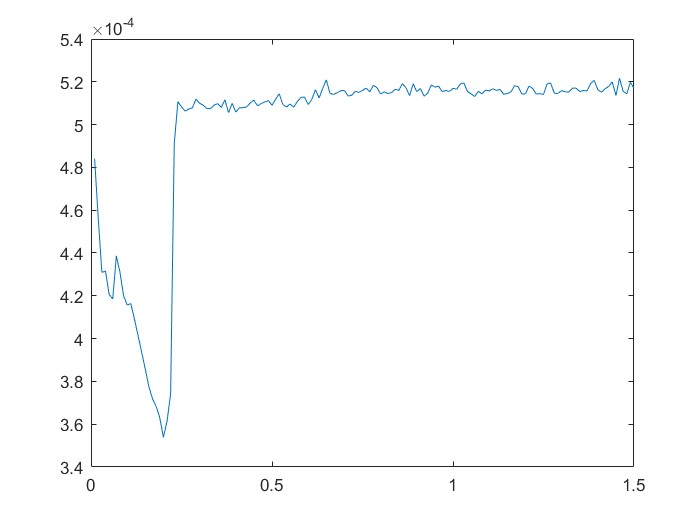

plot(ProportionDonationHistory,LossHistory)

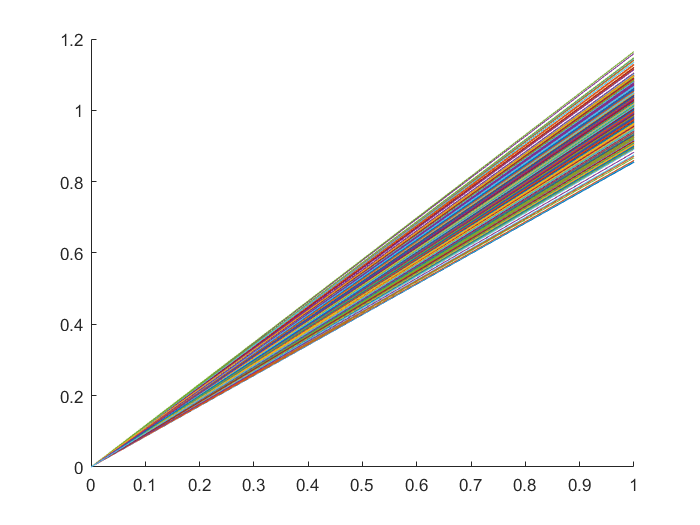

X = zeros(1000,2);
Y = zeros(1000,2);
figure
hold on
for i = 1:1000
    Y(i,2) =normrnd(1,0.05);
    X(i,2) =1;
    plot(X(i,:),Y(i,:))
end